Vs = sym('V_s')

$$Vs = V_{s}$$

L = sym('L')

$$L = L$$

C = sym('C')

$$C = C$$

R = sym('R')

$$R = R$$

D = sym('D')

$$D = \text{D}$$

s = sym('s')

$$s = s$$


Vs_ = 300

Vs_ = 300

L_ = 10e-3

L_ = 0.0100

C_ = 4.7e-6

C_ = 4.7000e-06

R_ = 100

R_ = 100

D_ = 0.5

D_ = 0.5000


Aon = [0, 0; 0, -1/(R*C)]

$$Aon = \left(\begin{array}{cc} 0 & 0\\ 0 & -\frac{1}{C\,R} \end{array}\right)$$

Bon = [1/L; 0]

$$Bon = \left(\begin{array}{c} \frac{1}{L}\\ 0 \end{array}\right)$$

Con = [sym(0), 1]

$$Con = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$


Aoff = [0, -1/L; 1/C, -1/(R*C)]

$$Aoff = \left(\begin{array}{cc} 0 & -\frac{1}{L}\\ \frac{1}{C} & -\frac{1}{C\,R} \end{array}\right)$$

Boff = [sym(0); 0]

$$Boff = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Coff = [sym(0), 1]

$$Coff = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$


A_p = Aon*D + Aoff*(1-D)

$$A\_p = \left(\begin{array}{cc} 0 & \frac{\text{D}-1}{L}\\ -\frac{\text{D}-1}{C} & \frac{\text{D}-1}{C\,R}-\frac{\text{D}}{C\,R} \end{array}\right)$$

B_p = Bon*D + Boff*(1-D)

$$B\_p = \left(\begin{array}{c} \frac{\text{D}}{L}\\ 0 \end{array}\right)$$

C_p = Con*D + Coff*(1-D)

$$C\_p = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$


Hs = (C_p/(s*eye(2)-A_p))*B_p

$$Hs = -\frac{\text{D}\,R\,\left(\text{D}-1\right)}{R\,{\text{D}}^{2}-2\,R\,\text{D}+C\,L\,R\,s^{2}+L\,s+R}$$

Hsest = subs(Hs,s,0)

$$Hsest = -\frac{\text{D}\,R\,\left(\text{D}-1\right)}{R\,{\text{D}}^{2}-2\,R\,\text{D}+R}$$

Voest = subs((Hs*Vs),[Vs,L,C,R,D,s],[Vs_,L_,C_,R_,D_,0])

$$Voest = 300$$

Xest = subs((s*eye(2)-A_p)\B_p*Vs,s,0)

$$Xest = \left(\begin{array}{c} \frac{\text{D}\,V_{s}}{R\,{\text{D}}^{2}-2\,R\,\text{D}+R}\\ -\frac{\text{D}\,R\,V_{s}\,\left(\text{D}-1\right)}{R\,{\text{D}}^{2}-2\,R\,\text{D}+R} \end{array}\right)$$

% PASOS:
% 1) Calcular simbolicamente Vo_D
% 2) Extraer simbolicamente numerador y denominador
% 3) Extraer simbolicamente coeficientes de numerador y denominador
% 4) Reemplazar símbolos por valores numéricos
% 5) Realizar transferencia

Vo_D = (C_p/(s*eye(2)-A_p))*((Aon-Aoff)*Xest+(Bon-Boff)*Vs)+(Con-Coff)*Xest

$$Vo\_D = \begin{array}{l} -\frac{L\,R\,\left(\text{D}-1\right)\,\left(\frac{V_{s}}{L}-\frac{\text{D}\,R\,V_{s}\,\left(\text{D}-1\right)}{L\,\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+R\right)}\right)}{\sigma_{1}}-\frac{\text{D}\,L\,R\,V_{s}\,s}{\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+R\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=R\,{\text{D}}^{2}-2\,R\,\text{D}+C\,L\,R\,s^{2}+L\,s+R \end{array}$$

Vo_D = simplify(Vo_D)

$$Vo\_D = \frac{V_{s}\,\left(R+{\text{D}}^{2}\,R-2\,\text{D}\,R-\text{D}\,L\,s\right)}{{\left(\text{D}-1\right)}^{2}\,\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+C\,L\,R\,s^{2}+L\,s+R\right)}$$

simplify(subs(Vo_D,[Vs,L,C,R,D],[Vs_,L_,C_,R_,D_]))

$$ans = -\frac{1200\,\left(\frac{s}{200}-25\right)}{\frac{5548780617371833\,s^{2}}{1180591620717411303424}+\frac{s}{100}+25}$$


%Vo_D_ = subs(Vo_D,[Vs,L,C,R,D],[Vs_,L_,C_,R_,D_])

[num,den] = numden(Vo_D)

$$num = V_{s}\,\left(R+{\text{D}}^{2}\,R-2\,\text{D}\,R-\text{D}\,L\,s\right)$$

$$den = {\left(\text{D}-1\right)}^{2}\,\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+C\,L\,R\,s^{2}+L\,s+R\right)$$

numc = coeffs(num,s)%double(coeffs(num))

$$numc = \left(\begin{array}{cc} V_{s}\,\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+R\right) & -\text{D}\,L\,V_{s} \end{array}\right)$$

denc = coeffs(den,s)%double(coeffs(den))

$$denc = \left(\begin{array}{ccc} {\left(\text{D}-1\right)}^{2}\,\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+R\right) & L\,{\left(\text{D}-1\right)}^{2} & C\,L\,R\,{\left(\text{D}-1\right)}^{2} \end{array}\right)$$

%an = numc(1)
%bn = numc(2)
%cn = numc(3)
%ad = denc(1)
%bd = denc(2)
%cd = denc(3)

numc_ = double(subs(numc,[Vs,L,C,R,D],[Vs_,L_,C_,R_,D_]))

numc_ = 	1.0e+03 *

    7.5000   -0.0015


denc_ = double(subs(denc,[Vs,L,C,R,D],[Vs_,L_,C_,R_,D_]))

denc_ =     6.2500    0.0025    0.0000



sys = tf(numc_,denc_)

sys =
 
           7500 s - 1.5
  -------------------------------
  6.25 s^2 + 0.0025 s + 1.175e-06
 
Continuous-time transfer function.



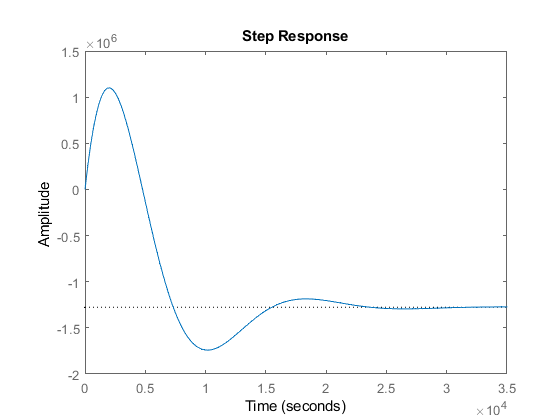

step(sys)

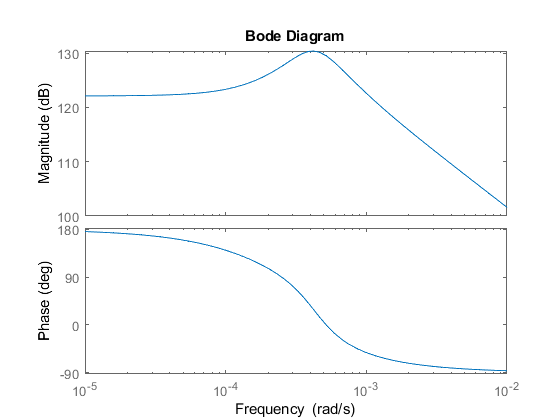

bode(sys)

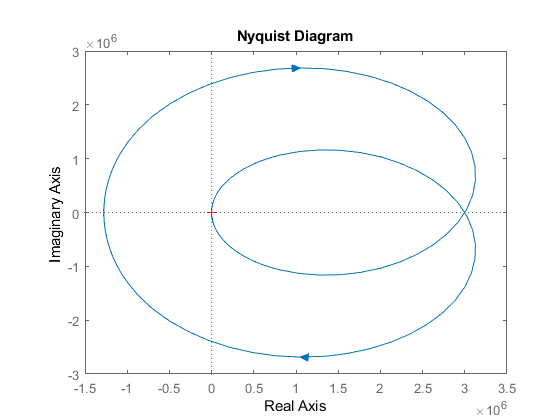

nyquist(sys)